###  Задание 2. Следящий регулятор по состоянию. 

Начальные данные для задания:

A = [12 -1 14; 
    6 0 6; 
    -6 -2 -8];
B = [11; 7; -7];

% Bf = [0 2 -1 0; 
%       0 0 0 0; 
%       0 -2 0 0];
Bf = [0 0 0 0; 
      0 0 0 0; 
      0 0 0 0];


C = [-2 2 -1];
Cz = [2 1 3];

G = [-40 16 9 -7;
    -64 25 14 -12; 
    -26 11 7 -3; 
    48 -18 -14 8];

D = [6; -6; -4; -5];
Dz = [-8 -2 8 -5];

w_0 = [1; 1; 1; 1];
x_0 = [1; 1; 1];

e = eig(G)

e =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


#### Считаем  K1, K2

Q = eye(3);
R = 1;
[K1,~,~] = lqr(A, B, Q, R);
K1 = -K1

K1 =     8.7057   -8.6171    8.4715


eig(A + B*K1)

ans =   -14.3859
   -3.4708
   -2.0000


mat2tex(K1, 2)

\begin{bmatrix}
    8.71 & -8.62 & 8.47 \\
\end{bmatrix}


ans =     "\begin{bmatrix}
         8.71 & -8.62 & 8.47 \\
     \end{bmatrix}"



cvx_begin sdp;
variable P(3,4);
variable Y(1,4);

P*G - A*P == B*Y;
Cz*P + Dz == 0;
cvx_end;

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.3e-01|4.6e+03|1.2e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  2 
 1|1.000|0.967|5.8e-03|1.5e+02|8.9e+03| 0.000000e+00  2.014253e+02| 0:0:00| chol  2  2 
 2|1.000|0.976|3.3e-05|3.7e+00|6.9e+01| 0.000000e+00  2.597151e+00| 0:0:00| chol  2  2 
 3|1.000|0.989|4.4e-07|4.2e-02|4.5e-01| 0.000000e+00  3.406230e-02| 0:0:00| chol  2  1 
 4|1.000|0.98


K2 = Y - K1*P

K2 =    -0.6470   -1.2051   17.1163    7.8553


mat2tex(K2, 2)

\begin{bmatrix}
    -0.65 & -1.21 & 17.12 & 7.86 \\
\end{bmatrix}


ans =     "\begin{bmatrix}
         -0.65 & -1.21 & 17.12 & 7.86 \\
     \end{bmatrix}"


###  Выполнить следующее компьютерное моделирование...

### Разомкнутая система, u=0...

B = [0; 0; 0]; % Простым взмахом руки
out = sim('ex1.slx','ReturnWorkspaceOutputs','on');
t = out.tout;
x = out.x.data';

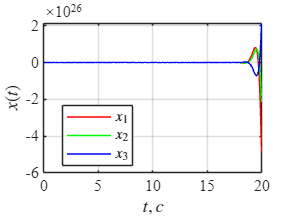

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("x4")

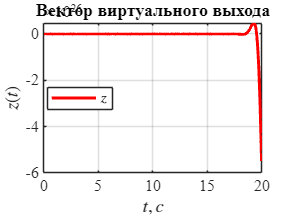

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z4")

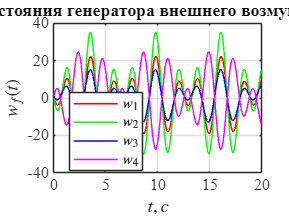

w = out.w.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, w(4, :), 'magenta', 'LineWidth', 1.0);
title('Состояния генератора внешнего возмущения')
xlabel('$t,c$','Interpreter','latex')
ylabel('$w_f(t)$', 'Interpreter','latex')
grid on
legend('$w_1$','$w_2$','$w_3$','$w_4$', ...
    'Location','best', 'Interpreter','latex')
save_file("w2")

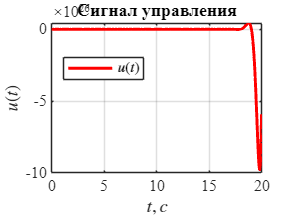

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u4")

### Замкнули регулятором только с K1 компонентой

B = [11; 7; -7]; % возвращаем всё на свои места
% K2 = [-0.6470   -1.2051   17.1163    7.8553 ];
K2 = [0 0 0 0];
out = sim('ex1.slx','ReturnWorkspaceOutputs','on');
t = out.tout;
x = out.x.data';

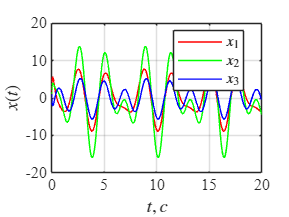

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("x5")

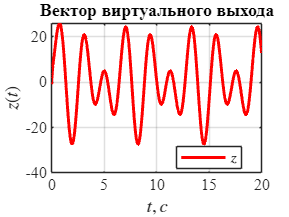

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z5")

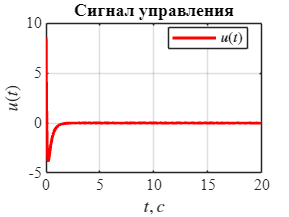

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u5")

### Замкнули полным регулятором

K2 = [-0.6470   -1.2051   17.1163    7.8553 ]; % возвращаем всё на свои места
out = sim('ex1.slx','ReturnWorkspaceOutputs','on');
t = out.tout;
x = out.x.data';

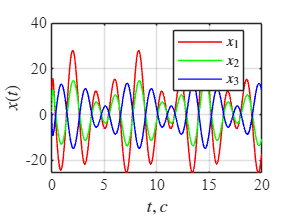

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("x6")

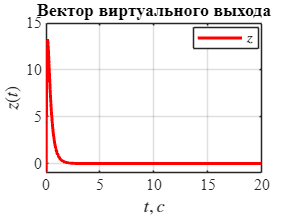

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z6")

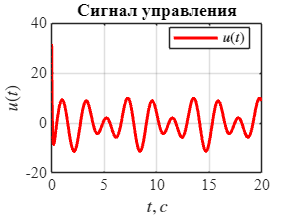

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u6")

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab12\latex12\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');
end